% This program extratcts of the data from material depletion during extrusion of polypropylene.
% 
% Material is polypropylelne
% Inner diameter of cylinder and syringe are 16 and 15.8 mm, respectively.
% Operating temperature is 160 degreeC.
% Initial absolute extrusion pressure is 140.15 kPa.
% Detection threshold is 2 kPa in 500 ms.
% 
% system_t           is time from the system log.
% system_t_depletion is depletion time from the system log.
% system_ps          is pressure from the system log.
% system_lc          is the inner longitudinal distance of cylinder from the system log.

feedrate = '1000'; % feedrate of cylinder in micron/s (available feedrate value: 1000)

data_filename = ['depletion_dataset_f' feedrate '.mat'];
load(data_filename)

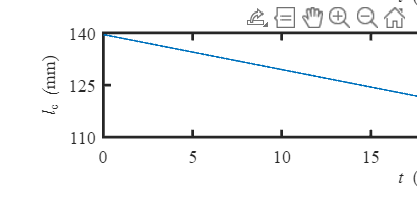

figure
figure
fig = gcf;
fig.Units = 'centimeters';
fig.Position = [10 5 15.5 7.5];

color = colororder('gem');

ax1 = subplot(2,1,1);

xline(system_t_depletion,'--k','LineWidth',1);
hold on
l1 = plot(system_t,system_ps,'-','LineWidth',1);

ax1.Units = 'centimeters';
ax1.FontName = 'Times New Roman';
ax1.FontSize = 10;
ax1.LineWidth = 1.5;
ax1.Box = 'on';
ax1.Position = [2 4.75 12 2];
xlim(ax1,[0 35])
xticks(ax1,0:5:35)
ylim([floor(min(system_ps)/10)*10 ceil(max(system_ps)/10)*10])
yticks(linspace(floor(min(system_ps)/10)*10,ceil(max(system_ps)/10)*10,3))

xlabel(ax1,'\fontname{Times New Roman}\itt \rm(s)','FontSize',10)
ylabel(ax1,'\fontname{Times New Roman}\itP_{\rms}\fontname{Times New Roman} (\rmkPa)','FontSize',10)

ax2 = subplot(2,1,2);

xline(system_t_depletion,'--k','LineWidth',1);
hold on
l2 = plot(system_t,system_lc,'-','LineWidth',1);

ax2.Units = 'centimeters';
ax2.FontName = 'Times New Roman';
ax2.FontSize = 10;
ax2.LineWidth = 1.5;
ax2.Box = 'on';
ax2.Position = [2 1.25 12 2];
xlim(ax2,[0 35])
xticks(ax2,0:5:35)
ylim([floor(min(system_lc)/10)*10 ceil(max(system_lc)/10)*10])
yticks(linspace(floor(min(system_lc)/10)*10,ceil(max(system_lc)/10)*10,3))

xlabel(ax2,'\fontname{Times New Roman}\itt \rm(s)','FontSize',10)
ylabel(ax2,'\fontname{Times New Roman}\itl_{\rmc}\fontname{Times New Roman} (\rmmm)','FontSize',10)